clear 
close 

# Greybox parameter identification for structurally restricted MTI models

Structurally restricted MTI-models can be obtained by utilizing orthogonal ternary vector lists (OTVL). Detailed descriptions of the dependencies between OTVL and MTI-models can be taken from [1,2].

[Open Live Script in Matlab](matlab:open("Demo_GreyBoxIdentificationOTVL.mlx"))

## Representation of multilinear equations as OTVL

We have multilinear equations 


$$\begin{array}{l}
x_1 \left(k+1\right)=0\\
x_2 \left(k+1\right)=\left(1-x_1 \left(k\right)\right)\left(1-x_2 \left(k\right)\right)x_3 \left(k\right)+x_1 \left(k\right)\left(1-x_2 \left(k\right)\right)+\left(1-x_1 \left(k\right)\right)x_2 \left(k\right)\left(1-x_3 \left(k\right)\right)\\
x_3 \left(k+1\right)=\left(1-x_1 \left(k\right)\right)\left(1-x_3 \left(k\right)\right)+x_1 \left(k\right)x_3 \left(k\right)\ldotp 
\end{array}$$


**Equation 1: multilinear equations**

with OTVL


$$z_1' = \matrix{
\mathbf{z_1} & \mathbf{z_2} & \mathbf{z_3} \cr \hline \cr
 & &
}; \qquad
z_2' = \matrix{
\mathbf{z_1} & \mathbf{z_2} & \mathbf{z_3} \cr \hline
0 & 0 & 1 \cr
1 & 0 & - \cr
0 & 1 & 0
};  \qquad
z_3' = \matrix{
\mathbf{z_1} & \mathbf{z_2} & \mathbf{z_3} \cr \hline
0 & - & 0\cr
1 & - & 1
}
$$


representing the structure of the state equations.

Those equations can be represented as OTVL: 

%create OTVL structures for state equations
myTvlStruct1 = false(0,0,2);
myTvlStruct1(:,:,1) = zeros(0,3); %position of dont cares
myTvlStruct1(:,:,2) = zeros(0,3); %Boolean values
myTvlStruct2 = false(3,3,2);
myTvlStruct2(:,:,1) = [0 0 0; 0 0 1; 0 0 0]; %position of dont cares
myTvlStruct2(:,:,2) = [0 0 1; 1 0 0; 0 1 0]; %Boolean values
myTvlStruct3 = false(2,3,2);
myTvlStruct3(:,:,1) = [0 1 0; 0 1 0]; %position of dont cares
myTvlStruct3(:,:,2) = [0 0 0; 1 0 1]; %Boolean values

%create  OTVLs
myOTvl1 = otvl(myTvlStruct1);
myOTvl2 = otvl(myTvlStruct2);
myOTvl3 = otvl(myTvlStruct3);

The Boolean values of the OTVL are represented in a 3D-array, with the third dimension indicating the 0, 1 and $-$ of the OTVL.


$$0\, (\text{logical false}) = [0\;0]$$



$$1\, (\text{logical true}) = [0 \;1]$$



$$- \, (\text{don't care operator}) = [1 \; 0]$$


## Create a structurally restriced MTI model

In order to obtain a structurally restricted MTI model, continuous valued parameters are added to the multilinear equations: 


$$\begin{array}{l}
x_1 \left(k+1\right)=c_1 \\
x_2 \left(k+1\right)=\phi_1 \left(a_{21} -x_1 \left(k\right)\right)\left(a_{22} -x_2 \left(k\right)\right)\left(x_3 \left(k\right)+a_{13} \right)+\phi_2 \left(x_1 \left(k\right)+a_{11} \right)\left(a_{22} -x_2 \left(k\right)\right)+\phi_3 \left(a_{21} -x_1 \left(k\right)\right)\left(x_2 \left(k\right)+a_{12} \right)\left(a_{23} -x_3 \left(k\right)\right)+c_2 \\
x_3 \left(k+1\right)=\phi_4 \left(a_{21} -x_1 \left(k\right)\right)\left(a_{23} -x_3 \left(k\right)\right)+\phi_5 \left(x_1 \left(k\right)+a_{11} \right)\left(x_3 \left(k\right)+a_{23} \right)+c_3 \ldotp 
\end{array}$$


**Equation 2: parametized state equations**

Those parameters are saved in arrays of dimensions $F_\phi \in \mathrm{R}^{5\times1}; F_a \in \mathrm{R}^{2\times3}; F_c\in\mathrm{R}^{3\times1}$. When setting all $\phi_i$ to values of 1 and all $a_{\textrm{ij}}$ and $c_i \;$to values of 0, the structural model information contained in Equation 1 is obtained. 

myPhi = ones(5,1); %dimension: total TVL rows x 1
myA = zeros(2,3); %dimension: 2 x number of variables
myC = zeros(3,1); %dimension: number of equations x 1

%adjusting the model parameters
myPhi(2,1) = 0.7;
myPhi(5,1) = 0.5;
myA(1,2) = 0.4;
myA(2,3) = 0.2;
myC(1,1) = 0.9;

Structural model information and parameters are then summarized in an otvlTens object. 

oTens = otvlTens(myPhi, myA, myC, myOTvl1, myOTvl2, myOTvl3)

oTens =   otvlTens with properties:

        structure: {[1×1 otvl]  [1×1 otvl]  [1×1 otvl]}
             FPhi: [5×1 double]
               Fa: [2×3 double]
               Fc: [3×1 double]
    equationCount: 3
       inputCount: 0


Now a multilinear state space system can be created:

timestep = 1;
omss = mss(oTens,timestep)

omss =   mss with properties:

     F: [1×1 otvlTens]
     G: [0×0 mtiTens]
     n: 3
     m: 0
     p: 0
    ts: 1


## Simulation of a structurally restricted MTI model

A simulation of a structurally restricted MTI model can be performed by providing initial conditions and a vector of timesteps.

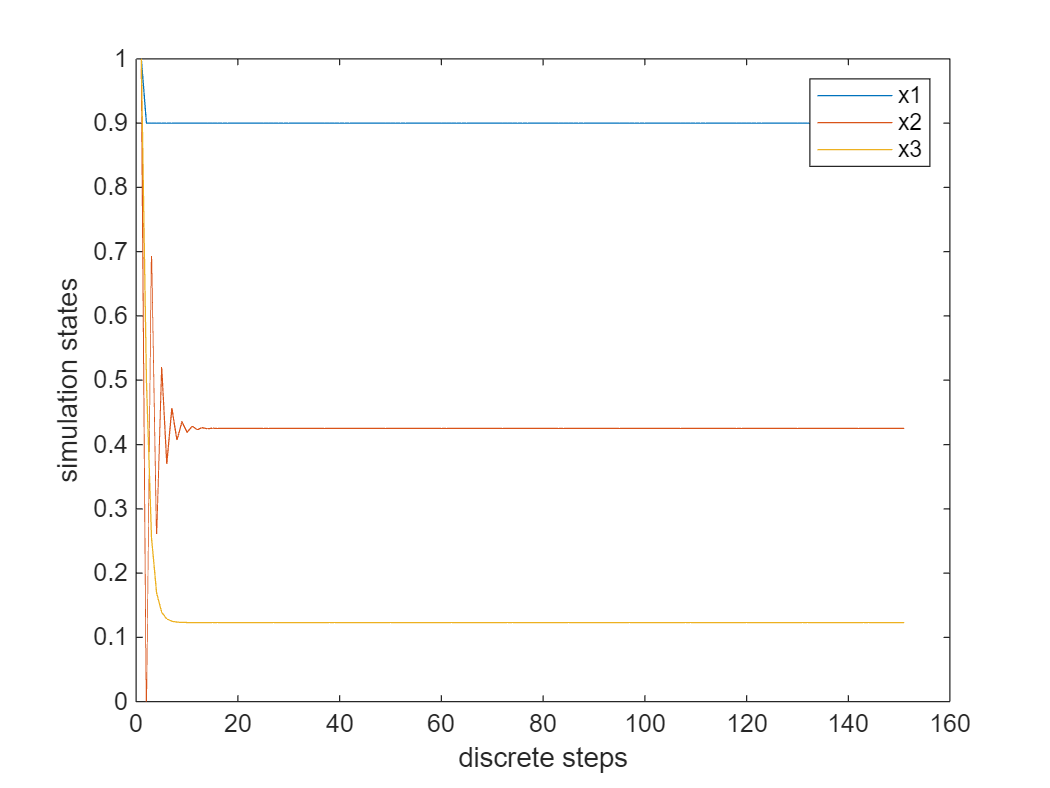

x0 = [1 1 1]; %initial condition
tEnd = 150; %end time

%perform simulation
myX = msim(omss,[],1:tEnd,x0); 

figure()
plot(1:tEnd+1, myX)
xlabel('discrete steps')
ylabel('simulation states')
legend('x1', 'x2', 'x3')

## Identification of the model parameters of a structurally restricted MTI model

Multilinear model identification for a given multilinear structure can be performed for data, that is given as an iddata object. The maximum identification rank is currently set to 1.

Identification finished: number of iterations: 199, number of initializations: 1, final cost: 0.54074


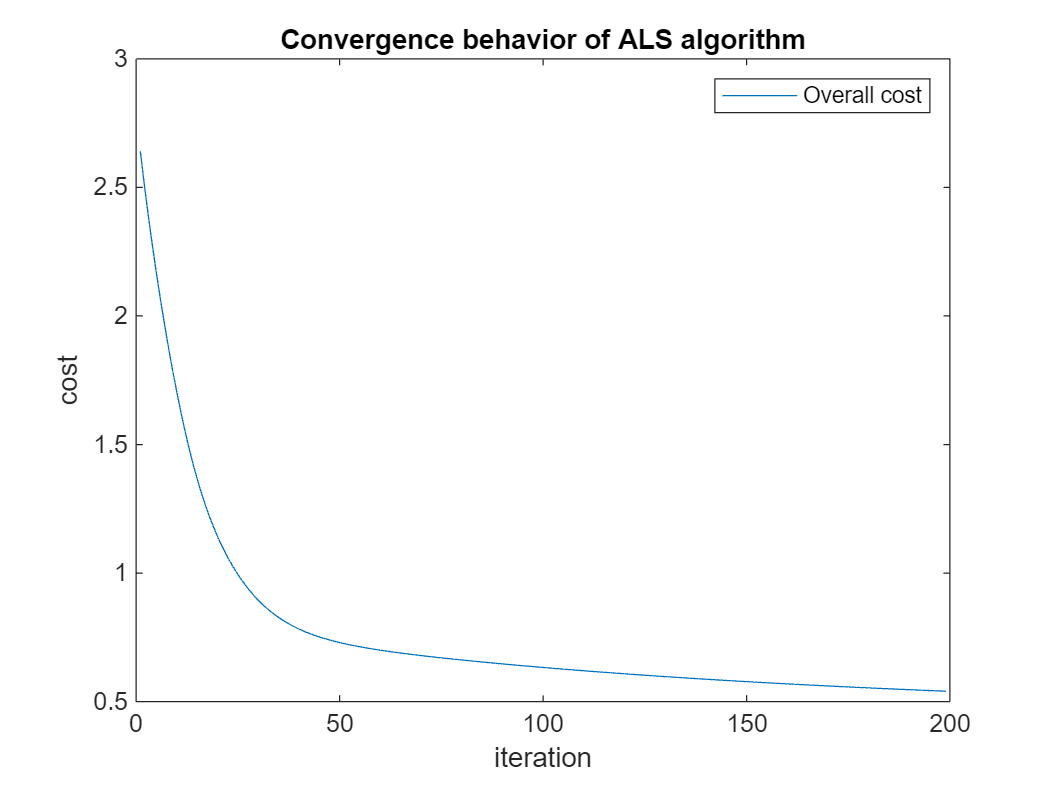

load('xDataNoisy.mat')

rank = 1;
[sysID, costID] = mlgreyest(xDataNoisy,rank,oTens,"Focus","prediction", "Display","on");

%simulation of identified model
omssID = mss(sysID, timestep)

omssID =   mss with properties:

     F: [1×1 otvlTens]
     G: [0×0 mtiTens]
     n: 3
     m: 0
     p: 0
    ts: 1


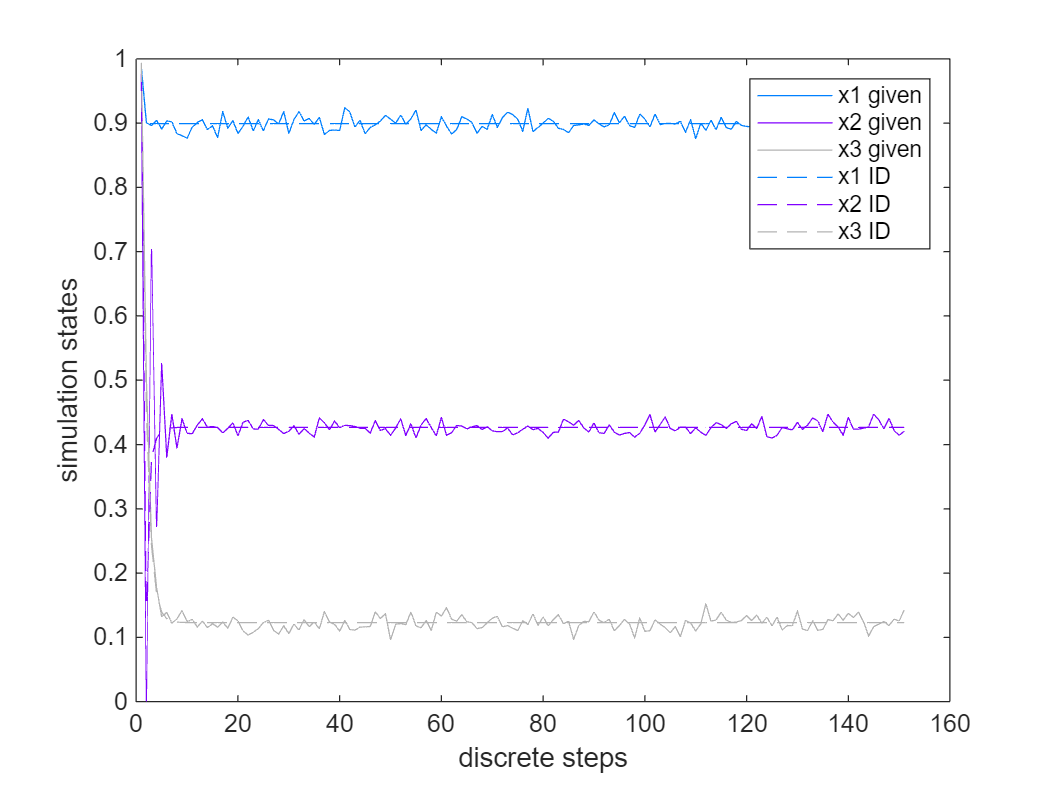

simID = msim(omssID, [],1:tEnd, xDataNoisy.y(1,:));
newcolors = [0 0.5 1; 0.5 0 1; 0.7 0.7 0.7];

figure()
colororder(newcolors)
plot(1:length(xDataNoisy.y), xDataNoisy.y,1:tEnd+1,simID, '--')
xlabel('discrete steps')
ylabel('simulation states')
legend('x1 given', 'x2 given', 'x3 given', 'x1 ID', 'x2 ID', 'x3 ID');

#### References

[1] M. Engels, G. Lichtenberg, and S. Knorn, “An approach to structured multilinear modeling with relaxed Boolean output functions” in 22nd IFAC World Congress, Yokohama, Japan, 2023

[2] M. Engels, G. Lichtenberg, and S. Knorn, “An approach to parameter identification for Boolean-structured multilinear time-invariant models” in ECC 2024, Stockholm, Sweden